# Clase especial - Audio

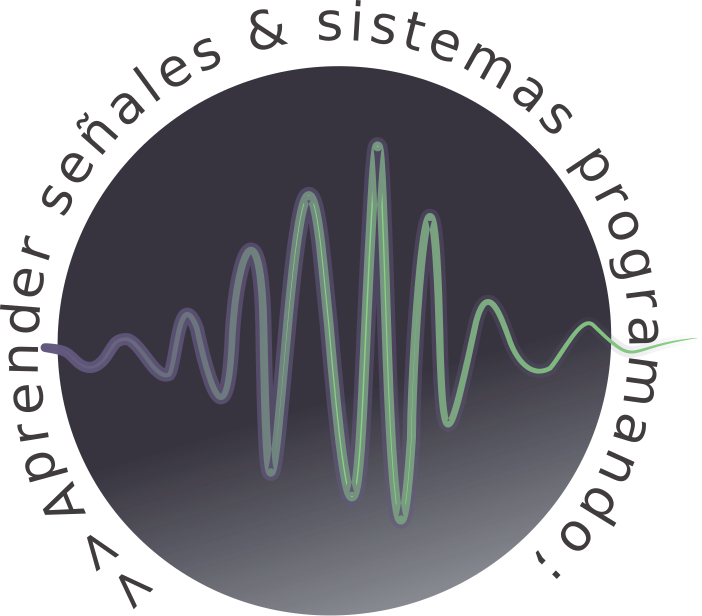

# Temario

- Introducción.

- audioread - audiowrite.

# Introducción

Las funciones de audio de MATLAB leen y almacenan datos de audio de un solo canal (mono) en una matriz de una columna, y datos en dos canales (estéreo) en una matriz de dos columnas. Para datos estéreo, la primera columna contiene el canal izquierdo, y la segunda columna contiene el canal derecho.

Normalmente, cada muestra tiene un valor de doble precisión (64 bits) entre -1 y 1. **En algunos casos, particularmente cuando el hardware de audio no admite profundidades de bits altas, los archivos de audio almacenan los valores como enteros de 8 bits o 16 bits**. El rango de los valores de muestra depende del número de bits disponibles. Por ejemplo, las muestras almacenadas como valores uint8 pueden variar de 0 a 255 (28 - 1). Las funciones de `sound `y `soundsc` de MATLAB solo admiten valores de precisión simple o doble entre -1 y 1. Otras funciones de audio admiten múltiples tipos de datos, como se indica en las páginas de referencia de funciones.

help sound

 sound Play vector as sound.
    sound(Y,FS) sends the signal in vector Y (with sample frequency
    FS) out to the speaker on platforms that support sound. Values in
    Y are assumed to be in the range -1.0 <= y <= 1.0. Values outside
    that range are clipped.  Stereo sounds are played, on platforms
    that support it, when Y is an N-by-2 matrix.
 
    sound(Y) plays the sound at the default sample rate of 8192 Hz.
 
    sound(Y,FS,BITS) plays the sound using BITS bits/sample if
    possible.  Most platforms support BITS=8 or 16.
 
    Example:
      load handel
      sound(y,Fs)
    You should hear a snippet of Handel's Hallelujah Chorus.
 
    See also soundsc, audioplayer.

    Reference page for sound



help soundsc

 soundsc Autoscale and play vector as sound.
    soundsc(Y,...) is the same as SOUND(Y,...) except the data is
    scaled so that the sound is played as loud as possible without
    clipping.  The mean of the dynamic range of the data is set to
    zero after the normalization.
 
    soundsc(Y,...,SLIM) where SLIM = [LOW HIGH] linearly scales  values in
    Y in the range [LOW, HIGH] to [-1, 1].  Values outside [LOW, HIGH] are
    scaled beyond [-1, 1] and will be clipped when played back on a sound
    device. By default, SLIM is [-MAX(ABS(Y)) MAX(ABS(Y))]. 
 
    See also sound, audioplayer, audiorecorder.

    Reference page for soundsc



La señal de audio en un archivo representa una serie de muestras que capturan la amplitud (y) del sonido a lo largo del tiempo. La frecuencia de muestreo (fs) es la cantidad de muestras discretas tomadas por segundo y expresadas en hertz. La precisión de las muestras, medida por la profundidad del bit (número de bits por muestra), depende del hardware de audio disponible.

El registro de una señal sonora puede guardarse en distintos formatos, como pueden ser **.wav**, **.flac **, **.mp3**, **.mp4 **, **.m4a **o **.ogg** ([+info](https://es.wikipedia.org/wiki/Formato_de_archivo_de_audio)) , y esta información se encuentra guardada en el disco duro o en un dispositivo de almacenamiento externo. Para procesar estos datos en MATLAB, necesitamos ubicarlos en memoria, es decir, crear una variable, un vector o una matriz con dicha información.

**Para ello, MATLAB dispone de dos funciones: **`audioread` **y **`wavread`** . La primera está disponible desde la versión 2011 de Matlab y la segunda sigue vigente en las versiones más recientes, aunque al utilizarse aparecerá un mensaje de aviso en la ventana de comandos comunicando que pronto quedará obsoleta. **

# audioread - audiowrite

Estas funciones no permiten trabajar en real-time (en tiempo real). Dada la actualidad de este apunte y las ventajas de `audioread `sobre` wavread`, solo estudiaremos la primer función, aunque cabe aclarar que ambas tienen una forma de funcionamiento muy similar. **La principal ventaja (como habrán deducido por el nombre) es que wavread ****solo es compatible con archivos en formato .wav mientras que audioread ****admite todos los formatos mencionados anteriormente.**

Comencemos con un pequeño ejemplo, confiando que el lector del apunte está haciendo uso de las herramientas de ayuda para entender el funcionamiento de estas funciones, mientras lee con mucho detenimiento:  

MATLAB cuenta con muchos archivos de audio de muestra, para probar los scripts, el link con el detalle de los mismo es el sigueinte: [Sample Audio Files](https://la.mathworks.com/help/audio/ug/sample-audio-files.html).

arch_audio = 'speech_dft_8kHz.wav';
[y,fs]  = audioread(arch_audio);
info = audioinfo(arch_audio) % metadata del archivo de audio

info =              Filename: '/usr/local/MATLAB/R2016b/toolbox/dsp/dspdemos/speech_dft_8kHz.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 8000
         TotalSamples: 39922
             Duration: 4.9902
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


ty = 0:seconds(1/fs):seconds(info.Duration);
ty = ty(1:end-1);

sound (y, fs)

Si se desea detener un `sound`, ingresar `clear sound` en command window.

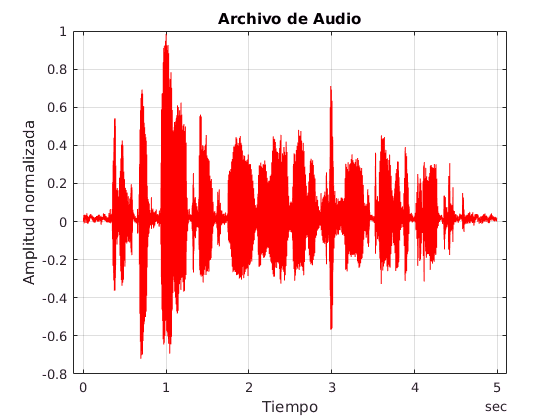

plot(ty, y, '-r');
    title ('Archivo de Audio')
    xlabel ('Tiempo')
    ylabel ('Amplitud normalizada')
    grid on

Cómo se puede apreciar en el ejemplo, `audioread` tiene una variable de entrada, la cual es una variable tipo string que contiene la información del nombre y path del archivo en la computadora. En el caso del ejemplo, el archivo se encuentra en los path generales de MATLAB, único lugar en el cual se buscará el archivo especificado. Si el archivo se encuentra localizado en cualquier otra carpeta, hay que especificar la ruta completa del mismo, para evitar recibir un mensaje de error en la ventana de comandos. `audioread` devuelve dos variables, en el ejemplo nombradas como `y` y `fs` . 

Con lo visto hasta el momento, el lector de este apunte ya se encuentra en condiciones de cargar un archivo de audio en una matriz y procesar dicha información. Ahora, veamos la forma de reproducir dichos vectores, o de guardar el contenido de una variable en un archivo de audio. Para ello usaremos `audiowrite` (Como en el caso anterior, esta última función también está disponible a partir de las versiones más recientes de MATLAB y se utiliza de una forma muy similar a la próxima versión obsoleta: wavwrite).  

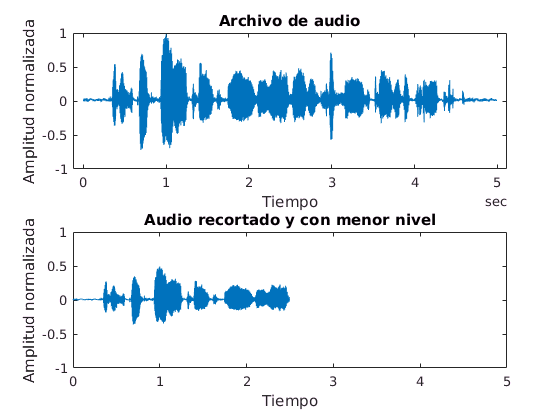

x = y(1:fix(length(y)/2))/2; % recorte temporal de la señal y amplitud
tx = (0:length(x)-1)/fs; % nuevo vector temporal

subplot(2,1,1)
    plot(ty, y);
        title 'Archivo de audio'
        xlabel 'Tiempo'
        ylabel 'Amplitud normalizada'
subplot(2,1,2)
    plot(tx, x);
        title 'Audio recortado y con menor nivel'
        xlabel 'Tiempo'
        ylabel 'Amplitud normalizada'
        xlim([0 5])
        ylim([-1 1])

audiowrite('audio_modif.wav',x,fs)
pause(5)
soundsc(x,fs)

La función `audiowrite` es la que nos permite crear una archivo (en este caso **.wav**) y sus argumentos de entrada son: Nombre del archivo, matriz con información y frecuencia de sampleo (También permite guardar metadata, pero no viene al caso). Es importante, como en el caso anterior, especificar toda la ruta del archivo. Ingresando solamente el nombre, este se guardará en la carpeta de trabajo (current folder).

# Archivos de audio

si se intenta abrir un archivo de audio como en los ejemplos vistos, y aumente la amplitud para que las muestras superen el valor unitario (en vez de dividir por 2, multiplique por un valor conveniente, mientras más muestras superen dicho valor mejor servirá el ejemplo) y utilice la función `audiowrite `para guardar el archivo (tipo single). Luego, utilice un reproductor para escuchar. ¿Qué ocurrió? Dos cosas: Primero escuchó el efecto del saturador que acaba de crear, y segundo, aparece este mensaje en la ventana de comandos:

audiowrite('audio_sat.wav',y*10,fs)

Matlab no guarda valores que superan en módulo al valor 1. Esos son los límites. Si ocurre que, como en este caso, se intentase, los valores que superan la unidad son reemplazados con valores unitarios. Por ejemplo, una muestra con valor 2 se guarda como si fuese 1. Un -1 o un 1 son tomados como el valor máximo de tensión eléctrica limite de salida del conversor digital-analogico. Eso también quiere decir, que el nivel de escucha físico (presión sonora) está condicionado por el conversor y su sistema de sonido. Si el lector pudiera cambiar el conversor de su computadora, es posible que el valor de tensión eléctrica cambie, modificando el nivel de presión sonora resultante. En la siguiente figura se ejemplifica elefecto de utilizar la función audiowrite con una matriz la cual contiene valores que superan los límites establecidos.

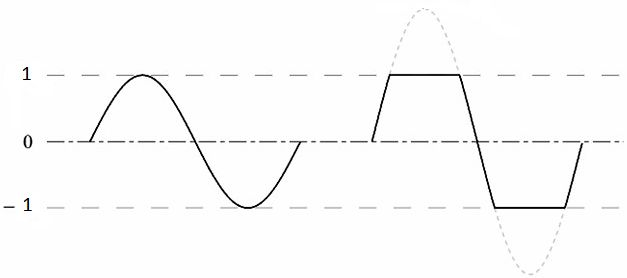

Lo mismo ocurre a la hora de grabar audio. Los niveles están limitados por el conversor analogico-digital y eso se refleja cuando se escribe un archivo. Si se sobrepasa el nivel de tensión eléctrica que admite el conversor, el resultado será el valor digital máximo del mismo, para cada valor de tensión superado. Entonces, cuando se obtenga un vector en Matlab con la información del archivo resultante, veremos a la señal “recortada” en amplitud, sin superar nunca, en módulo, el valor 1. En la siguiente figura se especifica cómo se modifica una señal tipo senoidal cuando se superan los límites máximos de tensión de entrada de un conversor. 

Es por esto que no se puede saber el valor que representan las muestras guardadas, ni encontrar la relación valor-presión sonora, porque el valor de cada muestra depende del sistema de sonido con el que se realizó el registro del mencionado fenómeno físico. El único caso, es cuando se conocen todas las condiciones del sistema, como nivel de presión sonora, relación presión-tensión del transductor, configuración del amplificador, y relación tensión-valor digital del conversor. Otra opción (más accesible y utilizable) es tener el registro de una señal que sirva para calibrar el sistema. ¿Cómo? Si se tuviese un dispositivo capaz de entregar un nivel de presión sonora conocido (94 dB SPL, por ejemplo), y se pudiera realizar un registro con nuestro sistema de dicha señal y observar los valores digitales obtenidos, se podría encontrar la relación presión sonora-valor digital tan deseada, y conocer que representan físicamente los valores de cada muestra obtenida.

De esta forma, es como se realiza un instrumental de medición digital. Si la configuración no se ve modificada por ningún motivo, y se cuenta con un dispositivo calibrador (dispositivo que produce una magnitud física conocida) que tampoco se ve modificado, es posible establecer la relación analogica-digital con presición. Con lo mencionado anteriormente, solo faltaría conocer la forma de adquirir datos del conversor analogico-digital (placa de audio) desde Matlab para almacenar los valores entregados en memoria.

# Audio System Toolbox

Audio System Toolbox™ [[+info](https://la.mathworks.com/products/audio-system.html)] está **optimizado para procesamiento de audio en tiempo real**. Los siguientes objetos trabajan en tiempo real: 

- *audioDeviceReader*

- *audioDeviceWrite*

- *dsp.AudioFileReader*

- *dsp.AudioFileWrite*

deviceReader = audioDeviceReader;
devices = getAudioDevices(deviceReader)

devices =     'Default'    'HDA Intel PCH: ALC3260 Analog (hw:0,0)'    'sysdefault'    'pulse'    'ALSAdefault'



deviceWriter = audioDeviceWriter;
devices = getAudioDevices(deviceWriter)

devices =     'Default'    'HDA Intel PCH: ALC3260 Analog (hw:0,0)'    'HDA Intel PCH: HDMI 0 (hw:0,3)'    'sysdefault'    'front'    'surround40'    'surround51'    'surround71'    'hdmi'    'pulse'    'dmix'    'ALSAdefault'


Antes de trabajar con este Toolbox (o framework) es primordial enterder como trabaja MATLAB con el flujo de procesos en tiempo real.

# Input & output audio

Los metodos/objetos que manejan los** inputs **de audio son:

- *dsp.AudioFileReader*: flujo de audio **desde un archivo**.

- *audioDeviceReader:* flujo de audio **desde un dispositivo**. Este objeto permite especificar el driver, los dispositivos de entrada y sus atributos (buffer, frecuencia de muestreo, resolucion, entre otros).

Los metodos/objetos que manejan los **outputs **de audio son:

- *dsp.AudioFileWriter*: flujo de audio **a un archivo**.

- *audioDeviceWriter:* flujo de audio **a un dispositivo**. Este objeto permite especificar el driver, los dispositivos de entrada y sus atributos (buffer, frecuencia de muestreo, resolucion, entre otros)

## Flujo input (*audioDeviceReader*)

El siguiente grafico describe el flujo de datos** general** (monocanal) desde el sistema de adquisición/reproducción (placa de sonido) hasta MATLAB.

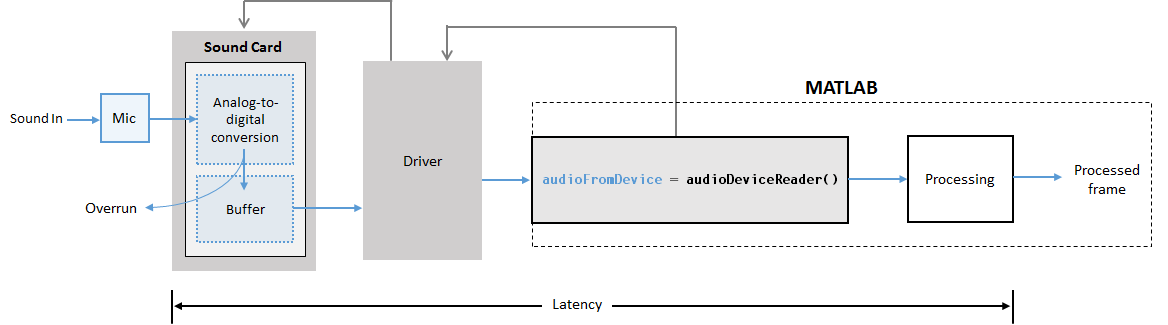

- El micrófono recoge el sonido y envía una señal eléctrica continua a la tarjeta de sonido.

- La tarjeta de sonido realiza la conversión de analógico a digital a una frecuencia de muestreo, tamaño de búffer y resolución especificada por el objeto *audioDeviceReader*.

- El conversor analógico-digital escribe muestras de audio en el búffer de la tarjeta de sonido. Si el buffer está lleno, se colocan las muestras nuevas.

- *audioDeviceReader *utiliza el driver para enviar a MATLAB desde el frame más antiguo de forma iterativa.

Comencemos a trabajar con el objeto más básico, *audioDeviceReader:*

doc audioDeviceReader 

## 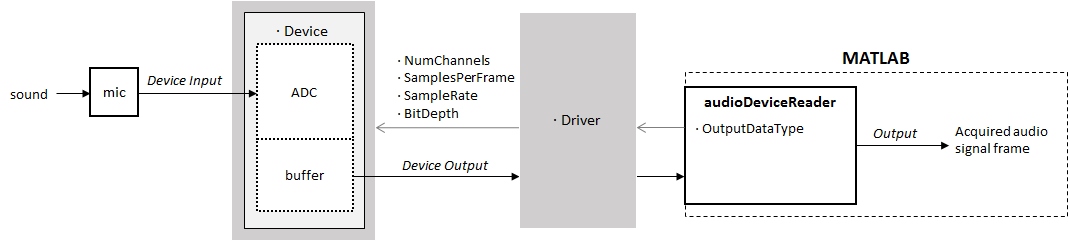

Objetivo: Grabar 10 segundos de voz con un micrófono y enviar la salida a un archivo `.wav` .

deviceReader = audioDeviceReader;
    deviceReader.SamplesPerFrame = 512;
    deviceReader.SampleRate = 44100;
setup(deviceReader) ;% Función de MATLAB para autoconfigurar objetos y dismunir la carga computacional
fileWriter = dsp.AudioFileWriter('test_adq.wav', 'FileFormat', 'WAV') % Utilizo AudioFileWriter

fileWriter =   dsp.AudioFileWriter with properties:

      Filename: 'test_adq.wav'
    FileFormat: 'WAV'
    SampleRate: 44100
    Compressor: 'None (uncompressed)'
      DataType: 'int16'


disp('Adquisición iniciada ...')

Adquisición iniciada ...


tic;

Grabar 10 segundos de discurso en un **audio** **stream loop**, leer un frame de la señal de audio  desde el dispositivo y escribir en un archivo especifico. El archivo se guarda en la carpeta actual.

while toc < 11 % Bucle de frame
    audioFromDevice = deviceReader();
    fileWriter(audioFromDevice);
% Para versiones previas a R2016b
%     audioFromDevice = step(deviceReader);
%     step(fileWriter,audioFromDevice);
end
disp('Adquisición finalizada.')

Adquisición finalizada.


release(deviceReader)
release(fileWriter) 

Utilizando lo aprendido anteriormente, escuchemos que se grabo (usando funciones no real-time):

clear y ty
arch_audio = 'test_adq.wav';
[y,fs]  = audioread(arch_audio);
sound(y,fs)
info = audioinfo(arch_audio) % metadata del archivo de audio

info =              Filename: '/home/maxi/Gdrive/Laboral/UNTREF/Señales & Sistemas/Contenido/Practica/Matlab/Clases/Clases especiales/Audio/LiveScript/test_adq.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 484352
             Duration: 10.9830
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


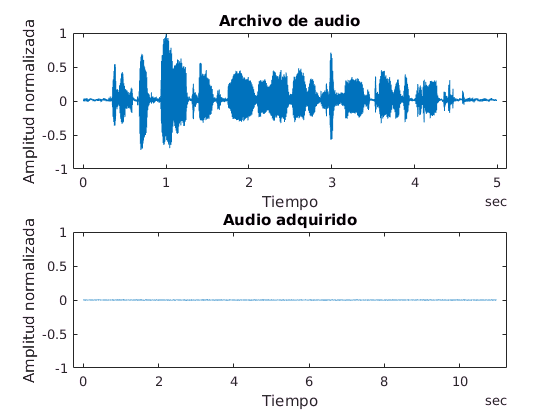

ty = 0:seconds(1/fs):seconds(info.Duration);
ty = ty(1:end-1);
plot(ty, y);
        title 'Audio adquirido'
        xlabel 'Tiempo'
        ylabel 'Amplitud normalizada'
        ylim([-1 1])

## Optimizar el uso de *audioDeviceReader*

- **Latencia:** es el tiempo de retardo entre el audio que ingresa a la tarjeta de sonido y la salida del frame de la etapa de procesamiento. Para minimizar la latencia, se puede:

                                Optimizar la etapa de procesamiento, compilando el código en C utilizando MATLAB Coder™.

                                Disminuir la frecuencia de muestreo.

                                Disminuir el tamaño de frame.

- **Sobrecarga (overrun):** la sobrecarga de la señal de entrada se produce cuando la etapa de procesamiento no puede mantener el ritmo de adquisicion de las muestras

                                Optimizar la etapa de procesamiento.

                                Disminuir la frecuencia de muestreo.

                                Disminuir el tamaño de frame.

## Flujo Output (*audioDeviceWriter*)

El siguiente grafico describe el flujo de datos** general** (monocanal) desde MATLAB hasta el sistema de adquisición/reproducción (placa de sonido).

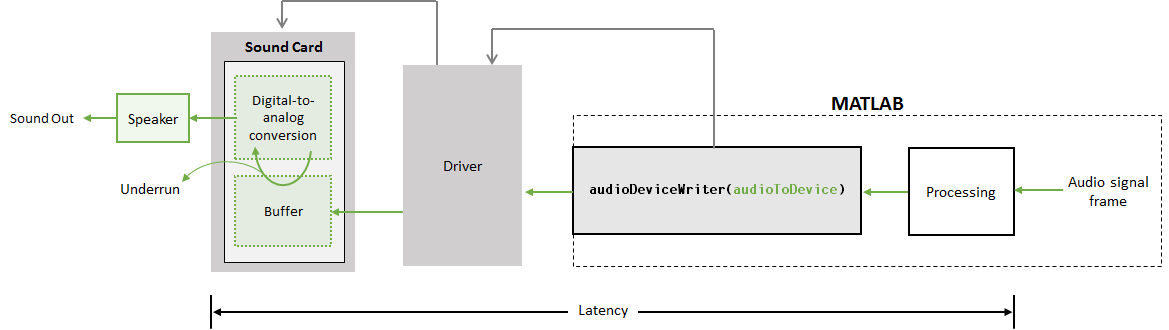

- La etapa de procesamiento pasa una estructura de longuitud variable al objeto *audioDeviceWriter*.

- *audioDeviceWriter *envia el frame al buffer de la tarjeta de sonido. El objeto de audioDeviceWriter especifica la frecuencia de muestreo, tamaño de búffer y resolución especificada de la tarjeta de sonido.

- *audioDeviceWriter *utiliza el driver para enviar desde el objeto audioDeviceWriter al conversor analogico digital, el frame más antiguo de forma iterativa.

Comencemos a trabajar con el objeto más básico, *audioDeviceWriter:*

doc audioDeviceWriter

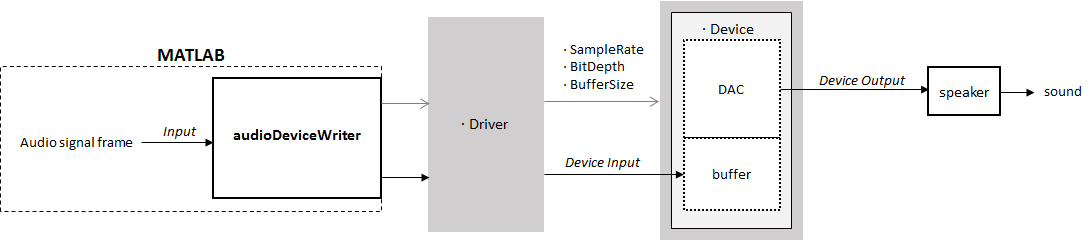

arch_audio = 'test_adq.wav';
fileReader = dsp.AudioFileReader(arch_audio); % Utilizo AudioFileReader
fileInfo = audioinfo(arch_audio)

fileInfo =              Filename: '/home/maxi/Gdrive/Laboral/UNTREF/Señales & Sistemas/Contenido/Practica/Matlab/Clases/Clases especiales/Audio/LiveScript/test_adq.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 484352
             Duration: 10.9830
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16



deviceWriter = audioDeviceWriter();
    deviceWriter.SampleRate = 44100;
    deviceWriter.BitDepth = '16-bit integer';
    
setup(deviceWriter,zeros(fileReader.SamplesPerFrame,fileInfo.NumChannels));

while ~isDone(fileReader) % Bucle de frame
    audioData = fileReader();
    deviceWriter(audioData);
% Para versiones previas a R2016b
%     audioData = step(fileReader);
%     step(deviceWriter,audioData);    
end

release(fileReader);
release(deviceWriter);


## Optimizar el uso de *audioDeviceWriter*

- **Latencia: **se mide como el tiempo de retardo entre la generación de un frame de sonido en MATLAB y la reproducción por el altavoz. Para minimizar la latencia, se puede:

                                Optimizar la etapa de procesamiento, compilando el código en C utilizando MATLAB Coder™.

                                Disminuir la frecuencia de muestreo.

                                Disminuir el tamaño de frame.

- **Underrun:** se refiere al silencio de la señal de salida. Silencio de señal de salida ocurre cuando el buffer está vacío.

                                Optimizar la etapa de procesamiento.

                                Disminuir la frecuencia de muestreo.

                                Aumentar el tamaño del frame.

                                Aumentar el tamaño del buffer. Se aplica solamente para señales de audio con logitud variable.

# Sincronizar input&output

SI la idea es leer y escribir en un solo dispositivo de audio se utiliza el objeto *audioPlayerRecorder, ***para versiones posteriores a R2016b.**

El dispositivo utilizado para reproducir y grabar datos de audio, debe estar habilitados para la reproducción simultánea y grabación (modo full-duplex, envío y recepción simultáneos). Utilice el método getAudioDevices para una lista de dispositivos disponibles.

Controladores compatibles para *audioPlayerRecorder* son específicas de la plataforma:

-     Windows: ASIO

-     Mac: CoreAudio

-     Linux: ALSA

Nota: Dispositivo de audio predeterminado es el dispositivo predeterminado de la máquina solamente si es compatible con modo full-duplex. Si el dispositivo de audio predeterminado de la máquina no es compatible con modo full-duplex, audioPlayerRecorder especifica como dispositivo predeterminado el primer dispositivo disponible detecta que es capaz de modo full-duplex. Utilice el método de info para obtener el nombre de dispositivo asociado con el objeto de audioPlayerRecorder.

En todo caso siempre es posible combinar lo aprendido para obtener el mismo resultado, en caso de poseer versiones anteriores de MATLAB.

# Respuesta de frecuencia de medida de un dispositivo de Audio 

En este ejemplo vamos afianzar los conocimiento aplicando lo aprendido y ademas agregar nuevos elementos para visualizar los datos adquiridos. Todos los elementos estan pensados para real-time.

La respuesta en frecuencia (RF) es una herramienta importante para la caracterización de un dispositivo de audio. Este ejemplo requiere un dispositivo de audio capaz de grabación y reproducción de audio y un driver de sonido apropiado.

Una medición de RF compara los niveles de salida de un dispositivo de audio a niveles de entrada conocidos.En este caso se realiza una medición de RF en el rango audible con un barrido senoidal. Una respuesta plana indica un dispositivo de audio que responde igualmente a todas las frecuencias.

## Setup de medición

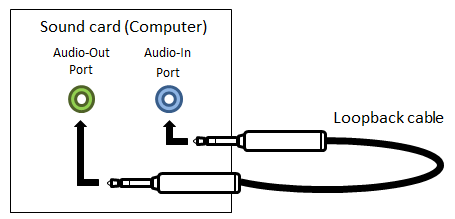

En este ejemplo, se mide el RF por medio de reproducir una señal de audio a través de `audioDeviceWriter` y después registrar la señal a través de `audioDeviceReader`. Un cable como de la imagen se utiliza para conectar físicamente el puerto de salida de audio de la tarjeta de sonido a su puerto de entrada de audio.

## Codigo

**Configuración de dispositivos**

Para comenzar, utilice el objeto de sistema de `audioDeviceReader `y `audioDeviceWriter` para conectar el dispositivo de audio. Este ejemplo utiliza un dispositivo de audio por defecto con una  frecuencia de muestreo de 48 kHz y un tamaño de búfer de 1024 muestras.

SampleRate = 48e3;

aDR = audioDeviceReader(...
      'SampleRate', SampleRate, ...
      'BitDepth', '16-bit integer', ...
      'ChannelMappingSource', 'Property', ...
      'SamplesPerFrame',1024,...
      'ChannelMapping', 1);

aDW = audioDeviceWriter(...
      'SampleRate', SampleRate, ...
      'BitDepth', '16-bit integer', ...
      'ChannelMappingSource', 'Property', ...
      'ChannelMapping', 1);
  
d = dialog('Position',[300 300 250 150],'Name','Frecuencia');

txt = uicontrol('Parent',d,...
               'Style','text',...
               'FontSize',30,...
               'Position',[20 80 210 40],...
               'String','0 Hz');

**Señal de prueba**

La señal de prueba es una onda sinusoidal con 1024 muestras por fotograma y una frecuencia inicial de 0 Hz. La frecuencia se aumenta en incrementos de 50 Hz a la gama audible.

SamplesPerFrame = 1024;
sineSource  = audioOscillator(...
      'Frequency', 0, ...
      'SignalType', 'sine', ...
      'SampleRate', SampleRate, ...
      'SamplesPerFrame', SamplesPerFrame);

**Analizador de espectro**

Utilizar el dsp `dsp.SpectrumAnalyzer` para visualizar el franco de su sistema de E/S audio. 20 medias de la estimación del espectro se utilizan durante todo el  experimento y se establece el ancho de banda de resolución a 50 Hz. Se establece la frecuencia de muestreo a 48 kHz.

RBW = 50;
Navg = 20;

scope = dsp.SpectrumAnalyzer(...
      'SampleRate', SampleRate, ...
      'FrequencySpan', 'Start and stop frequencies',...
      'StartFrequency', 20, ...
      'StopFrequency', 10000, ...
      'ReducePlotRate', false, ...
      'PlotAsTwoSidedSpectrum', false, ...
      'FrequencyScale', 'Log', ...
      'PlotMaxHoldTrace',true,...
      'ShowLegend', true, ...
      'YLimits', [-110 20],...
      'YLabel', 'Power', ...
      'Title', 'Respuesta en frecuencia');

**Lazo de medición de respuesta de frecuencia**

Para evitar el impacto del tiempo en la medición de la RF, precargamos el circuito de audio durante 5 segundos.

Una vez que comienza la medición de RF, se barre con la señal de prueba a través de la gama de frecuencia audible. Utilice el analizador de espectro para visualizar el RF.

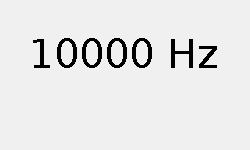

tic
while toc < 5
    x = sineSource();
    aDW(x);
    y = aDR();
    scope(y);
end

count = 1;
readerDrops = 0;
writerDrops = 0;

while true
    if count == Navg
        newFreq = sineSource.Frequency + RBW;
        if newFreq > 10000
            break
        end
        txt.String = [num2str(newFreq),' Hz'];
        sineSource.Frequency = newFreq;
        count = 1;
    end
    x = sineSource();
    writerUnderruns = aDW(x);
    [y,readerOverruns] = aDR();
    scope(y);
    count = count + 1;
end


release(aDR);
release(aDW);
release(scope);

Los datos del scope se extraen como si fuera una figure.